# ASSIGNMNET #2

## Example Usage

imageViewer("cameraman.tif",InitialMagnification=200)  

## Image Magnification

### Grayscale Conversion

image_rgb = imread("/MATLAB Drive/MATLAB-Assignment-2/Images/A2_berserk.jpeg");
imshow(image_rgb)

image_gray = im2gray(image_rgb);
imshow(image_gray) 

### Magnification

imageViewer(image_gray,InitialMagnification=77)  

## Image Contrasting

### Grayscale Conversion

domainExpansionRGB = imread("/MATLAB Drive/MATLAB-Assignment-2/Images/IMG_3894.JPG");
imshow(domainExpansionRGB)

domainExpansion = im2gray(domainExpansionRGB);
imshow(domainExpansion) % Display original image

### Contrasting

imageViewer(domainExpansion) % Opens Image viewer
imshow(domainExpansionContrast) % Displaying contrasted image

## Image Regions of Interest

### Grayscale Conversion

gojoRGB = imread("/MATLAB Drive/MATLAB-Assignment-2/Images/IMG_3895.JPG")

gojoRGB = 1687x1200x3 uint8 array
gojoRGB(:,:,1) =

    23    23    23    23    24    24    24    24    24    24    24    24    24    24    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    25    26    26    26    26    26    26    25    25    27    27    27    26    26    26    26    26    28    28    28    28    28    28    28    29    29    31    31    31    31    31    31    31    33    32    32    32    32    32    32    31    34    34    32    31    31    31    30    30    31    31    33    32    33    32    32    33    36    38    40    40    41    40    40    39    43    43    43    42    42    42    42    42    42    42    42    42    42    42    42    42    43    42    42    42    42    42    42    41    42    42    42    41    41    41    42    42    42    42    41    41    43    43    43    43    43    43    43    43    43    43    43    43    42    42    42    42    42    42

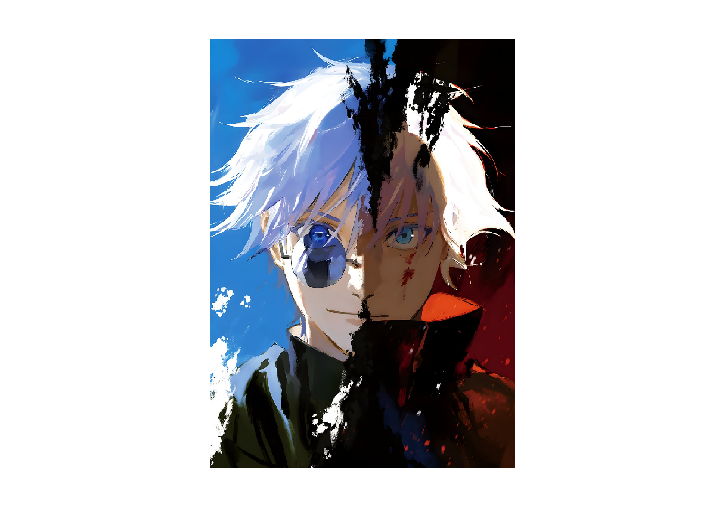

imshow(gojoRGB)


gojo = im2gray(gojoRGB);
imshow(gojo)

### Creating ROI

h = drawrectangle;
sixEyes = createMask(h)

sixEyes = 1687x1200 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

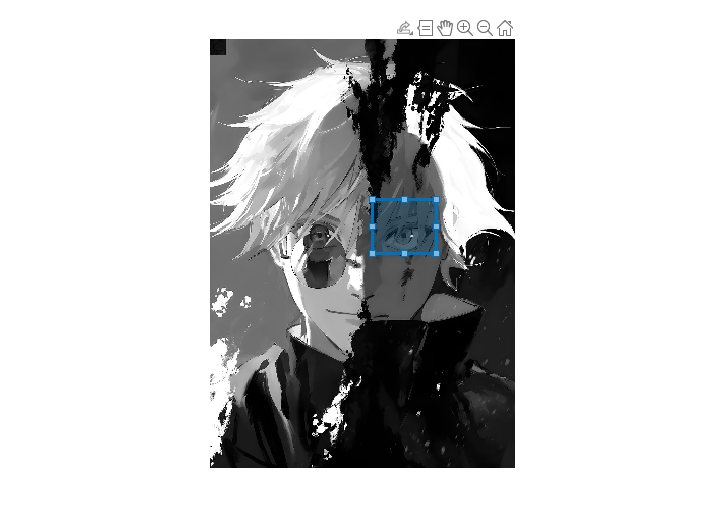

Operator '.*' is not supported for operands of type 'matlab.graphics.primitive.Image'.


roi = image .* uint8(sixEyes)

imshow(roi)

## Measuring Distances

## Inspecting Pixel Values